## **Implementacja metody adamsa dla liniowego równania różniczkowego**

Przykład dla k=2.

Wymaga podańa kroku h oraz warunku początkowego (punktu).


$$x_{n+1} =x_n +h\sum_{j=0}^{k-1} \gamma_j \nabla^j f_n$$


gdzie $\nabla^0 =f_n$ , $\nabla^{j+1} =\nabla^j f_n -\nabla^j f_{n-1}$, a $f_n =f\left(x,t\right)$ dla problemu zdefiniowanego jako $\dot{x} =f\left(x,t\right)$. Dodoatkowo wartości $\gamma$ obliczane są następująco $\gamma ={\left(-1\right)}^j \int_0^1 {\left({{-s}\atop{j}}\right)}\mathrm{ds}$ lub dla obliczonych już wartości odczynate z poniższej tabeli.

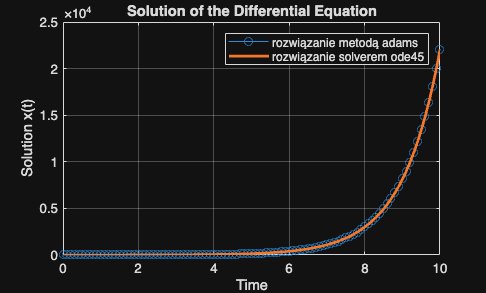

clear all;
% definicja kroku
h = 0.1;

% czas końcowy liczba próbek rozwiązania
tk = 10;
N = tk/h;

% definicja warunku początkowego
t0 = 0;
x0 = 0;

% inicjalizacja rozwiązania
Nx = N + 1;
x = zeros(1, N+1);
x(1) = x0;
% definicja funckji, równanie: dx = x + 1, f(x,t) = x+1
f = @(t, x) x + 1;

% obliczenie rozwiązania metodą adamsa dla k = 2
for n = 1 : Nx-1
    if n > 1
        x(n+1) = x(n) + h * (3/2 * f(0, x(n)) - 1/2 * f(0, x(n-1)));
    else
        x(n+1) = x(n) + h * ( 3/2 * f(0, x(n)) );
    end
end
% Wykreśl wynik
t = t0:h:tk;
figure;
plot(t, x, '-o');
xlabel('Time');
ylabel('Solution x(t)');
title('Solution of the Differential Equation');
grid on;

% porównanie z rzeczywistym rozwiązaniem równania różniczkowego
[t, y] = ode45(f, t, x0);

hold on;
plot(t, y, 'LineWidth', 2);
legend('rozwiązanie metodą adams', 'rozwiązanie solverem ode45')
hold off;

UWAGA! Dla małego h powstaje duży bias.

## Implementacja metody adams dla liniowego równania różniczkowego z opóźnieniem

Aby móc jednoznaczeni rozwiązać równanie różniczkowe z opóźnieniem należy oprócz równania podać warunek początkowy w postaci funkcji określonej na przedziale opóźnienia. Przykładowo:

$\dot{x} \left(t\right)=x\left(t-\tau \right)+x\left(t\right)+1$  , $\varphi \left(\theta \right)=0$ dla $\theta \in \left\lbrack -\tau ,0\right\rbrack \;$

clear all;
% definicja kroku
h = 0.1;

% czas końcowy liczba próbek rozwiązania
tk = 3;
N = tk/h;

% definicja funckji, równanie: dx = x + 1, f(x,t) = x(t - tau) + x(t) + 1
tau = 1;
f = @(t, x, xTau) xTau + x + 1;

% definicja warunku początkowego
phi = @(teta) exp(teta);
t0 = 0;

% inicjalizacja rozwiązania
Ntau = tau/h;
Nx = N + Ntau + 1;
x = zeros(1, Nx);
tetaSpan = -tau:h:0;
x(1:Ntau+1) = phi(tetaSpan);


% obliczenie rozwiązania metodą adamsa dla k = 2
for n = Ntau+1 : Nx-1
    if n > Ntau + 1
        x(n+1) = x(n) + h * (3/2 * f(0, x(n), x(n - Ntau)) - 1/2 * f(0, x(n-1), x(n - 1 - Ntau)));
    else 
        x(n+1) = x(n) + h * ( 3/2 * f(0, x(n), x(n - Ntau)));
    end
end
% Wykreśl wynik
t = t0-tau:h:tk;
figure;
plot(t, x, '-o');
xlabel('Time');
ylabel('Solution x(t)');
title('Solution of the Differential Equation with Time Delay');
grid on;
hold on;

% Rozwiązanie wbudowaną funkcją matlaba
lags = [tau];
tspan = [t0 tk];
ddefun = @(t, x, Z) Z(:,1) + x + 1;
sol = dde23(ddefun, lags, phi, tspan);
plot(sol.x, sol.y, 'LineWidth', 2);
legend('rozwiązanie metodą adams', 'rozwiązanie solverem dde23')

## Rozwiązanie TDS na podstawie wzoru analitycznego

Próba implementacji rozwiązania równania różniczkowego 


$$\dot{x} \left(t\right)=\mathrm{Ax}\left(t\right)+\mathrm{Bx}\left(t-\tau \right)+\mathrm{Cu}\left(t\right)$$


z wzoru


$$x\left(t\right)=e^{A\left(t-t_0 \right)} x\left(t_0 \right)+\int_{t_0 }^t e^{A\left(t-\theta \right)} \left(\mathrm{Bx}\left(\theta -\tau \right)+\mathrm{Cu}\left(\theta \right)\right)d\theta$$


Dla każdego $t_0 \ge 0$ oraz dla $t\in \left\lbrack t_0 ,t_0 +\tau \right\rbrack$.

Rozwiązanie uzyskiwane jest w sposób iteracyjny dla kolejnych przedziałów $t:t\in \left\lbrack \tau i+t_0 ,\left(i+1\right)\tau +t_0 \right\rbrack$. 

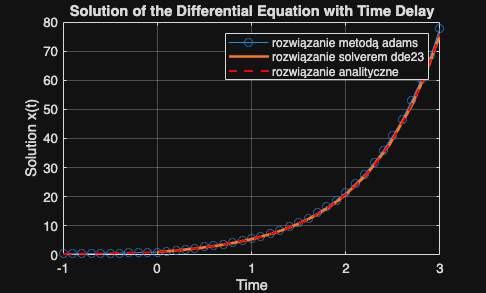

clear all; clc;
% Równanie różniczkowe: dx/dt = Ax(t) + Bx(t-tau) + Cu(t)
tau = 1;
A = 1;
B = 1;
C = 1;
u = @(t) 1;

% Warunek początkowy
phi = @(teta) exp(teta);

% Czas
tk = 3;
h = 0.05; % Zmniejszyłem krok dla dokładności całki
t = -tau:h:tk;

% Indeksy
delay_steps = round(tau/h);
start_idx = delay_steps + 1; % Indeks odpowiadający t=0

% Inicjalizacja rozwiązania
xSol = zeros(1, length(t));

% 1. Wypełnienie historii (-tau do 0)
for i = 1:start_idx
    xSol(i) = phi(t(i));
end

% 2. Obliczenie rozwiązania metodą kroków
% Dzielimy czas na przedziały [0, tau], [tau, 2tau], itd.
num_intervals = ceil(tk/tau);

for k = 1:num_intervals
    % Indeksy początku i końca obecnego interwału w tablicy t
    idx_start = start_idx + (k-1)*delay_steps;
    idx_end   = start_idx + k*delay_steps;
    
    % Zabezpieczenie, żeby nie wyjść poza zakres czasu tk
    if idx_end > length(t), idx_end = length(t); end
    
    % Warunek początkowy dla tego przedziału to ostatni punkt poprzedniego
    x_t0_interval = xSol(idx_start);
    t0_interval = t(idx_start);
    
    % Pętla po punktach wewnątrz interwału
    for i = (idx_start + 1) : idx_end
        t_current = t(i);
        
        % Część jednorodna: e^(A(t - t0)) * x(t0)
        homogeneous = exp(A * (t_current - t0_interval)) * x_t0_interval;
        
        % Część szczególna (całka splotowa): całkujemy od t0_interval do t_current
        integral_sum = 0;
        
        % Całkowanie numeryczne (metoda prostokątów)
        % Zmienna całkowania 's' biegnie od t0_interval do t_current
        for j = idx_start : i-1
            s = t(j);
            
            % Wartość opóźniona x(s - tau). 
            % W tablicy to indeks j pomniejszony o delay_steps
            x_delayed = xSol(j - delay_steps);
            
            % Funkcja podcałkowa: e^(A(t - s)) * (B*x(s-tau) + C*u(s))
            integrand = exp(A * (t_current - s)) * (B * x_delayed + C * u(s));
            
            integral_sum = integral_sum + integrand;
        end
        
        % Mnożymy sumę przez krok h! (To był główny brakujący element)
        integral_val = integral_sum * h;
        
        xSol(i) = homogeneous + integral_val;
    end
end

% Wykres
plot(t, xSol, 'r--', 'LineWidth', 1.5);
legend('rozwiązanie metodą adams', 'rozwiązanie solverem dde23', 'rozwiązanie analityczne')